##         Group 9 Initial Weight estimation - Matthew

Last updated 21:44 07/03/2024

#### Aircraft Setup 

%addpath(genpath('Functions'))
addpath(genpath('.')); % By any chance if line 1 could not recongize the
%function folder, please uncomment line 2 and comment line 1. This will
%happen with different computer setups and quite frankly, I have no idea
%why...
clear
aircraftname = "E"; %Select your aircraft

if aircraftname ~= "Other" %Limit No safety factor considered 
    AircraftData
else
    % Reference Aircraft = A320 
    Aircraft.Pax = 100; % [Human] Passengers onboard
    Aircraft.Bags = 50; %[kg] Checked in 
    Aircraft.Cargo = 100; %[kg] Checked Baggage 
    Aircraft.MaxPyld = 25000; % [kg] Max payload
    Aircraft.Range = 3350; % [nm] 
    Aircraft.CruiseMach = 0.75;
    Aircraft.Engines = 2;
    Aircraft.PaxWeight = 100;
    Aircraft.BagWeight = 15;
    Aircraft.AR = 9; % [-] Aspect Ratio, all aircraft assume ~9 
    Aircraft.e = 0.8; % [-] Oswald efficiency number
    Aircraft.CD0 = 0.018;
    Aircraft.c_TO = 0.3; 
    Aircraft.c_cruise = 0.565;
    Aircraft.c_climb = 0.565;
    Aircraft.c_approach = 0.565;
    Aircraft.CL_TO = 2.1;
    Aircraft.CL_Ld = 2.3;
    Aircraft.groundRollFraciton = 0.7;
    Aircraft.OEIPenalty = 0.3;
    Aircraft.ClimbDescentCredit = 200; %[nm]
    Aircraft.We_A = 0.97;
    Aircraft.We_exp = -0.06;
    Aircraft.CruiseAlt = 36000; %[ft] 
    Aircraft.reserveRatio = 1.05;
end

Aircraft = struct with fields:
                   Pax: 115
                  Bags: 115
                 Cargo: 1150
               MaxPyld: 17000
                 Range: 2681
            CruiseMach: 0.7500
               Engines: 2
             PaxWeight: 90
             BagWeight: 10
                    AR: 9.1200
                     e: 0.7800
                   CD0: 0.0186
                  c_TO: 0.2470
              c_cruise: 1.2411
               c_climb: 0.5650
            c_approach: 0.5650
                 CL_TO: 2.1000
                 CL_Ld: 2.3000
    groundRollFraciton: 0.2000
            OEIPenalty: 0.3000
    ClimbDescentCredit: 399
                  We_A: 0.9700
                We_exp: -0.0600
             CruiseAlt: 35000
          reserveRatio: 1.0500
           Constraints: [1×1 struct]


Aircraft = struct with fields:
                   Pax: 115
                  Bags: 115
                 Cargo: 1150
               MaxPyld: 17000
                 Range: 2681
            CruiseMach: 0.7500
               Engines: 2
             PaxWeight: 90
             BagWeight: 10
                    AR: 9.1200
                     e: 0.7800
                   CD0: 0.0186
                  c_TO: 0.2470
              c_cruise: 1.2411
               c_climb: 0.5650
            c_approach: 0.5650
                 CL_TO: 2.1000
                 CL_Ld: 2.3000
    groundRollFraciton: 0.2000
            OEIPenalty: 0.3000
    ClimbDescentCredit: 399
                  We_A: 0.9700
                We_exp: -0.0600
             CruiseAlt: 35000
          reserveRatio: 1.0500
           Constraints: [1×7 struct]


#### Aircraft Mission Segment

Note: Be careful with segments as this could varies between different aircrafts. Aircraft A B C all has the same segment so it remains as a temporary constant

%Segments for Aircraft
    warmupSegment = 0.995; %Assumed 
    takeOffSegment = 0.99; %Assumed
    climbSegment = 0.98; %Assumed
    cruiseSegment = getCruiseSegment(aircraftname); %Cruise function

Aircraft = struct with fields:
                   Pax: 115
                  Bags: 115
                 Cargo: 1150
               MaxPyld: 17000
                 Range: 2681
            CruiseMach: 0.7500
               Engines: 2
             PaxWeight: 90
             BagWeight: 10
                    AR: 9.1200
                     e: 0.7800
                   CD0: 0.0186
                  c_TO: 0.2470
              c_cruise: 1.2411
               c_climb: 0.5650
            c_approach: 0.5650
                 CL_TO: 2.1000
                 CL_Ld: 2.3000
    groundRollFraciton: 0.2000
            OEIPenalty: 0.3000
    ClimbDescentCredit: 399
                  We_A: 0.9700
                We_exp: -0.0600
             CruiseAlt: 35000
          reserveRatio: 1.0500
           Constraints: [1×1 struct]


Aircraft = struct with fields:
                   Pax: 115
                  Bags: 115
                 Cargo: 1150
               MaxPyld: 17000
                 Range: 2681
            CruiseMach: 0.7500
               Engines: 2
             PaxWeight: 90
             BagWeight: 10
                    AR: 9.1200
                     e: 0.7800
                   CD0: 0.0186
                  c_TO: 0.2470
              c_cruise: 1.2411
               c_climb: 0.5650
            c_approach: 0.5650
                 CL_TO: 2.1000
                 CL_Ld: 2.3000
    groundRollFraciton: 0.2000
            OEIPenalty: 0.3000
    ClimbDescentCredit: 399
                  We_A: 0.9700
                We_exp: -0.0600
             CruiseAlt: 35000
          reserveRatio: 1.0500
           Constraints: [1×7 struct]


    descentSegment = 0.995; %Assumed
    landingSegment = 0.995; %Assumed
    taxiSegment = 0.9990;%Assumed
    loiterSegment = getloiterSegment(aircraftname); % Loiter function 

Aircraft = struct with fields:
                   Pax: 115
                  Bags: 115
                 Cargo: 1150
               MaxPyld: 17000
                 Range: 2681
            CruiseMach: 0.7500
               Engines: 2
             PaxWeight: 90
             BagWeight: 10
                    AR: 9.1200
                     e: 0.7800
                   CD0: 0.0186
                  c_TO: 0.2470
              c_cruise: 1.2411
               c_climb: 0.5650
            c_approach: 0.5650
                 CL_TO: 2.1000
                 CL_Ld: 2.3000
    groundRollFraciton: 0.2000
            OEIPenalty: 0.3000
    ClimbDescentCredit: 399
                  We_A: 0.9700
                We_exp: -0.0600
             CruiseAlt: 35000
          reserveRatio: 1.0500
           Constraints: [1×1 struct]


Aircraft = struct with fields:
                   Pax: 115
                  Bags: 115
                 Cargo: 1150
               MaxPyld: 17000
                 Range: 2681
            CruiseMach: 0.7500
               Engines: 2
             PaxWeight: 90
             BagWeight: 10
                    AR: 9.1200
                     e: 0.7800
                   CD0: 0.0186
                  c_TO: 0.2470
              c_cruise: 1.2411
               c_climb: 0.5650
            c_approach: 0.5650
                 CL_TO: 2.1000
                 CL_Ld: 2.3000
    groundRollFraciton: 0.2000
            OEIPenalty: 0.3000
    ClimbDescentCredit: 399
                  We_A: 0.9700
                We_exp: -0.0600
             CruiseAlt: 35000
          reserveRatio: 1.0500
           Constraints: [1×7 struct]


    altClimb = 0.990;%Assumed
    altCruise = getDiversionSegment(aircraftname,100); % Diversion function 

Aircraft = struct with fields:
                   Pax: 115
                  Bags: 115
                 Cargo: 1150
               MaxPyld: 17000
                 Range: 2681
            CruiseMach: 0.7500
               Engines: 2
             PaxWeight: 90
             BagWeight: 10
                    AR: 9.1200
                     e: 0.7800
                   CD0: 0.0186
                  c_TO: 0.2470
              c_cruise: 1.2411
               c_climb: 0.5650
            c_approach: 0.5650
                 CL_TO: 2.1000
                 CL_Ld: 2.3000
    groundRollFraciton: 0.2000
            OEIPenalty: 0.3000
    ClimbDescentCredit: 399
                  We_A: 0.9700
                We_exp: -0.0600
             CruiseAlt: 35000
          reserveRatio: 1.0500
           Constraints: [1×1 struct]


Aircraft = struct with fields:
                   Pax: 115
                  Bags: 115
                 Cargo: 1150
               MaxPyld: 17000
                 Range: 2681
            CruiseMach: 0.7500
               Engines: 2
             PaxWeight: 90
             BagWeight: 10
                    AR: 9.1200
                     e: 0.7800
                   CD0: 0.0186
                  c_TO: 0.2470
              c_cruise: 1.2411
               c_climb: 0.5650
            c_approach: 0.5650
                 CL_TO: 2.1000
                 CL_Ld: 2.3000
    groundRollFraciton: 0.2000
            OEIPenalty: 0.3000
    ClimbDescentCredit: 399
                  We_A: 0.9700
                We_exp: -0.0600
             CruiseAlt: 35000
          reserveRatio: 1.0500
           Constraints: [1×7 struct]


    altLanding = 0.995; %Assumed
    reserveFuel = 1/Aircraft.reserveRatio; %Calculated
    
%Formatting segments into an array
    segment = [warmupSegment;takeOffSegment;climbSegment;cruiseSegment;descentSegment;...
    landingSegment;loiterSegment;taxiSegment;altClimb;altCruise;altLanding;reserveFuel];
    missionSegment = zeros(length(segment)); 


%Find the mission Segment: Indexes of segment * lastMissionSegment (W/ Exception) 
    for i = 1:length(segment)
        if i == 1 %Exception - First index of segment, missionSegment = warmupsegment
            missionSegment(1) = warmupSegment; 
            lastMissionSegment = missionSegment(1);
        else
          missionSegment(i) = segment(i)*lastMissionSegment;
          lastMissionSegment = missionSegment(i);
        end
    end

#### Weight Table

%Plotting the table
    segmentType = ["WARM";"TKOF";"CLMB";"CRUS";"DSCT";"LNDG";"HOLD";"TAXI";"ALCL";"ALCR";"ALLD";"RSRV"];
    Table = table(segment(:,1),missionSegment(:,1),segmentType(:,1), ...
        'VariableNames',["Segment Fraction","Mission Segment","Segment Type"])

Table = 12×3 table
    Segment Fraction    Mission Segment    Segment Type
    ________________    _______________    ____________

          0.995               0.995           "WARM"   
           0.99             0.98505           "TKOF"   
           0.98             0.96535           "CLMB"   
        0.64628             0.62389           "CRUS"   
          0.995             0.62077           "DSCT"   
          0.995             0.61767           "LNDG"   
        0.96483             0.59594           "HOLD"   
          0.999             0.59535           "TAXI"   
           0.99             0.58939           "ALCL"   
        0.99171             0.58451           "ALCR"   
          0.995             0.58159           "ALLD"   
        0.95238             0.55389           "RSRV"   


#### Weight Table

    passenger = Aircraft.Pax;
    bags = Aircraft.Bags;
    cargo = Aircraft.Cargo;
    maxPayload = Aircraft.MaxPyld;
    range = Aircraft.Range;
    passengerWeight = Aircraft.PaxWeight;
    bagWeight = Aircraft.BagWeight;
    MTOW = round(getWeightEstimation(missionSegment(12),aircraftname),-3);

Aircraft = struct with fields:
                   Pax: 115
                  Bags: 115
                 Cargo: 1150
               MaxPyld: 17000
                 Range: 2681
            CruiseMach: 0.7500
               Engines: 2
             PaxWeight: 90
             BagWeight: 10
                    AR: 9.1200
                     e: 0.7800
                   CD0: 0.0186
                  c_TO: 0.2470
              c_cruise: 1.2411
               c_climb: 0.5650
            c_approach: 0.5650
                 CL_TO: 2.1000
                 CL_Ld: 2.3000
    groundRollFraciton: 0.2000
            OEIPenalty: 0.3000
    ClimbDescentCredit: 399
                  We_A: 0.9700
                We_exp: -0.0600
             CruiseAlt: 35000
          reserveRatio: 1.0500
           Constraints: [1×1 struct]


Aircraft = struct with fields:
                   Pax: 115
                  Bags: 115
                 Cargo: 1150
               MaxPyld: 17000
                 Range: 2681
            CruiseMach: 0.7500
               Engines: 2
             PaxWeight: 90
             BagWeight: 10
                    AR: 9.1200
                     e: 0.7800
                   CD0: 0.0186
                  c_TO: 0.2470
              c_cruise: 1.2411
               c_climb: 0.5650
            c_approach: 0.5650
                 CL_TO: 2.1000
                 CL_Ld: 2.3000
    groundRollFraciton: 0.2000
            OEIPenalty: 0.3000
    ClimbDescentCredit: 399
                  We_A: 0.9700
                We_exp: -0.0600
             CruiseAlt: 35000
          reserveRatio: 1.0500
           Constraints: [1×7 struct]


    Aircraft.MTOW = MTOW;
    WeW0 = 0.97*MTOW^(-0.06);
    Aircraft.EmptyWeight = round(MTOW*WeW0,-3);
    DesignPayload = Aircraft.Pax*Aircraft.PaxWeight + Aircraft.Bags*Aircraft.BagWeight + Aircraft.Cargo; 
    MaxPayload = Aircraft.MaxPyld; 
    DesignFuel = round(MTOW * (1-missionSegment(12)),-3);
    WeightTbl = table([MTOW;Aircraft.EmptyWeight;DesignPayload;MaxPayload;DesignFuel],'RowNames',["Max Takeoff Weight", "Empty Weight", "Design Payload", "Maximum Payload", "Aircraft Design Fuel"],'VariableNames',"Weights (kg)")

WeightTbl = 5×1 table
                            Weights (kg)
                            ____________

    Max Takeoff Weight        1.57e+05  
    Empty Weight                 74000  
    Design Payload               12650  
    Maximum Payload              17000  
    Aircraft Design Fuel         70000  


### Payload Range Chart

[Max_payloadRange, weightRatio] = getpyldRangeEstimator(aircraftname,MTOW,Table);

Aircraft = struct with fields:
                   Pax: 115
                  Bags: 115
                 Cargo: 1150
               MaxPyld: 17000
                 Range: 2681
            CruiseMach: 0.7500
               Engines: 2
             PaxWeight: 90
             BagWeight: 10
                    AR: 9.1200
                     e: 0.7800
                   CD0: 0.0186
                  c_TO: 0.2470
              c_cruise: 1.2411
               c_climb: 0.5650
            c_approach: 0.5650
                 CL_TO: 2.1000
                 CL_Ld: 2.3000
    groundRollFraciton: 0.2000
            OEIPenalty: 0.3000
    ClimbDescentCredit: 399
                  We_A: 0.9700
                We_exp: -0.0600
             CruiseAlt: 35000
          reserveRatio: 1.0500
           Constraints: [1×1 struct]


Aircraft = struct with fields:
                   Pax: 115
                  Bags: 115
                 Cargo: 1150
               MaxPyld: 17000
                 Range: 2681
            CruiseMach: 0.7500
               Engines: 2
             PaxWeight: 90
             BagWeight: 10
                    AR: 9.1200
                     e: 0.7800
                   CD0: 0.0186
                  c_TO: 0.2470
              c_cruise: 1.2411
               c_climb: 0.5650
            c_approach: 0.5650
                 CL_TO: 2.1000
                 CL_Ld: 2.3000
    groundRollFraciton: 0.2000
            OEIPenalty: 0.3000
    ClimbDescentCredit: 399
                  We_A: 0.9700
                We_exp: -0.0600
             CruiseAlt: 35000
          reserveRatio: 1.0500
           Constraints: [1×7 struct]


    0.5815

    0.6784



Max_payloadRange = round(Max_payloadRange,0);
ferryRange = round(getferryRangeEstimator(aircraftname,MTOW,Table),0);

Aircraft = struct with fields:
                   Pax: 115
                  Bags: 115
                 Cargo: 1150
               MaxPyld: 17000
                 Range: 2681
            CruiseMach: 0.7500
               Engines: 2
             PaxWeight: 90
             BagWeight: 10
                    AR: 9.1200
                     e: 0.7800
                   CD0: 0.0186
                  c_TO: 0.2470
              c_cruise: 1.2411
               c_climb: 0.5650
            c_approach: 0.5650
                 CL_TO: 2.1000
                 CL_Ld: 2.3000
    groundRollFraciton: 0.2000
            OEIPenalty: 0.3000
    ClimbDescentCredit: 399
                  We_A: 0.9700
                We_exp: -0.0600
             CruiseAlt: 35000
          reserveRatio: 1.0500
           Constraints: [1×1 struct]


Aircraft = struct with fields:
                   Pax: 115
                  Bags: 115
                 Cargo: 1150
               MaxPyld: 17000
                 Range: 2681
            CruiseMach: 0.7500
               Engines: 2
             PaxWeight: 90
             BagWeight: 10
                    AR: 9.1200
                     e: 0.7800
                   CD0: 0.0186
                  c_TO: 0.2470
              c_cruise: 1.2411
               c_climb: 0.5650
            c_approach: 0.5650
                 CL_TO: 2.1000
                 CL_Ld: 2.3000
    groundRollFraciton: 0.2000
            OEIPenalty: 0.3000
    ClimbDescentCredit: 399
                  We_A: 0.9700
                We_exp: -0.0600
             CruiseAlt: 35000
          reserveRatio: 1.0500
           Constraints: [1×7 struct]


    0.6006



plot([0, Max_payloadRange, Aircraft.Range, ferryRange],[Aircraft.MaxPyld,Aircraft.MaxPyld,DesignPayload,0])
hold on
plot ([0, Max_payloadRange, Aircraft.Range],[DesignPayload,DesignPayload,DesignPayload],'--')
hold off
legend(["Fuel Limited", "Typical Payload"])
% 
xlabel("Range (nm)")
ylabel("Payload (kg)")
ax = gca;
chart = ax.Children(1);
chart.DataTipTemplate.DataTipRows(1).Label="Range";
chart.DataTipTemplate.DataTipRows(2).Label="Payload";
datatip(chart,Aircraft.Range,DesignPayload);
% 
chart2 =ax.Children(2);
chart2.DataTipTemplate.DataTipRows(1).Label="Range";
chart2.DataTipTemplate.DataTipRows(2).Label="Payload";
datatip(chart2,Max_payloadRange,Aircraft.MaxPyld);
% 
ax2 = gca;
chart3 = ax2.Children(2);
datatip(chart3,ferryRange,0);

hDataTip = findobj(gca,"DataIndex",3);
set(hDataTip,"X",4644,"Y",0);
hDataTip = findobj(gca,"DataIndex",4);
set(hDataTip,"X",2773,"Y",1.6e+04,"Location","southwest");
hDataTip = findobj(gca,"DataIndex",3);
delete(hDataTip)
FuelLimitedLine = findobj(gcf, "DisplayName", "Fuel Limited")

FuelLimitedLine =   Line (Fuel Limited) with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 2427 2681 3064]
              YData: [17000 17000 12650 0]

  Show all properties


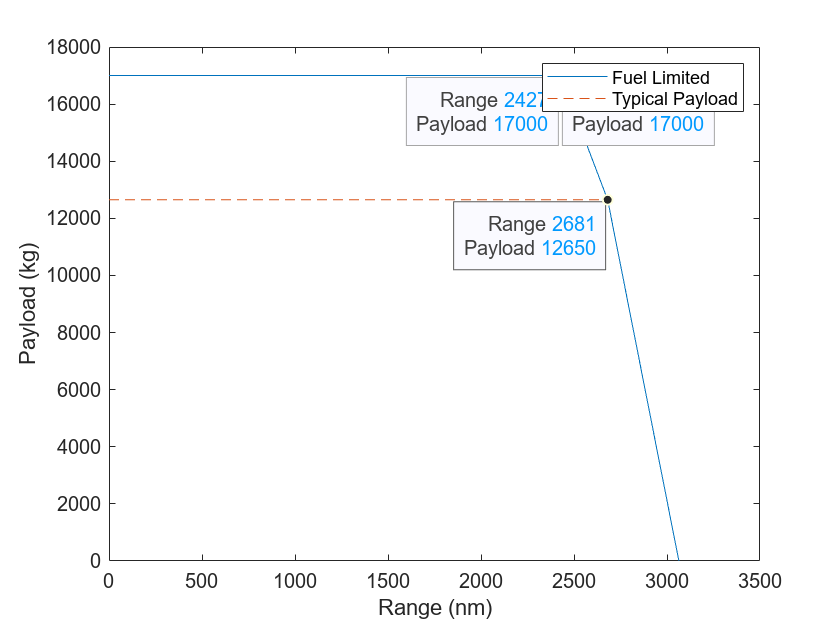

datatip(FuelLimitedLine,3350,1.35e+04,"Location","southwest");

#### CONSTRAIN ANALYSIS

% Constant definition
    WingLoading = linspace(1000,15000,281); 
    ThrustWeight = linspace(0,1,281);
    [turnClimbConstraint,takeOffConstraint,climbConstraint,cruiseConstraint,landingConstraint,ceilingConstraint,mu] = deal(zeros(281,1));

% Flight path angle
    alpha = atan(Aircraft.Constraints(2).ClimbGradient/100); % [Deg] Ex 2.4% gradient = 2.4m rised while 100m run

% Amosphereic properties [m]
    [~,~,rho,~] = get_AtmosProperties(4); 
    [~,~,rhoCruise,aCruise] = get_AtmosProperties(Aircraft.CruiseAlt*0.3048); %in meters
    [~,~,rhoCeiling,aCeiling] = get_AtmosProperties(Aircraft.Constraints(5).Altitude*0.3048); %in meters
% Finding properties 
    cruiseSpeed = Aircraft.CruiseMach*aCruise; % [m/s] True Airspeed @ Cruise
    qCruise = 1/2*rhoCruise*cruiseSpeed^2; % [kg/(m*s^2)] Dynamic pressure @ Cruise

    ceilingSpeed = Aircraft.Constraints(5).Mach*aCeiling; % [m/s] True airspeed @ Ceiling
    qCeiling = 1/2*rhoCeiling*ceilingSpeed^2; % [kg/(m*s^2)] Dynamic pressure @ Ceiling
    
    k = 1/(pi*Aircraft.e*Aircraft.AR); % [-] K factor 
    LD_climb = 1/sqrt(4*Aircraft.CD0*k); % [-] Lift/Drag @ Climb 
            [~,~,rhoKTEX,~] = get_AtmosProperties(2767);
% Finding turn climb Constraint's properties
    if aircraftname == 'E'
        [~,~,rhoTurn,aTurn] = get_AtmosProperties(Aircraft.Constraints(6).Altitude*0.3048); %in meters
        turnSpeed = Aircraft.Constraints(6).Mach*aTurn;
        qTurn = 1/2*rhoTurn*turnSpeed^2;
        n = sec(deg2rad(Aircraft.Constraints(6).BankAngle));
        gammaTurn = asin((Aircraft.Constraints(6).RateofClimb*0.00508)/turnSpeed); %[ft/min -> m/s]  
    end
% Main loop
    for i = 1:281 % 281 = Increments of 50 W/S [Nm^-2] between 15,000 and 1000 + 1 [15,000-1000/50 + 1 = 281] 
        takeOffConstraint(i) = (1.1^2/(Aircraft.CL_TO*rho*9.81*Aircraft.Constraints(1).Distance*0.01*Aircraft.Constraints(1).GroundRollFraction))*WingLoading(i); 
        % [-] Takeoff constraint with a tiny difference (0.006~ difference) 
        climbConstraint(i) = (alpha + 1/(LD_climb*(1-Aircraft.OEIPenalty)))*(Aircraft.Engines/(Aircraft.Engines-1)); 
        % [-] Climb constraint OEIpenalty is times by 0.7 (0.003~ difference) 
        cruiseConstraint(i) = (missionSegment(3)/Aircraft.Constraints(4).alpha)*(((Aircraft.CD0*qCruise)/(missionSegment(3)*WingLoading(i))...
            +((missionSegment(3)*k)/qCruise)*WingLoading(i))); 
        % [-] Cruise constraint Do not use Cruise mission Segment use climb's (Works spot on)
        ceilingConstraint(i) = (missionSegment(4)/Aircraft.Constraints(5).alpha)*(((Aircraft.CD0*qCeiling)/(missionSegment(4)*WingLoading(i))...
            +((missionSegment(4)*k)/qCeiling)*WingLoading(i)));
        % [-] Ceiling Constraint Use Cruise mission as max service ceiling apporaches at the end of cruise (B has a 0.1 difference*, rest is spot on)
        beta1 = missionSegment(5) * (weightRatio/segment(4));
        landingConstraint(i) = ((1/beta1)*(0.6*(Aircraft.Constraints(3).Distance-300)*9.81*0.4*rhoKTEX*Aircraft.CL_Ld))/(1.2^2); 
        % [-] Landing constraint ** AircraftEX's beta value is commented for Aircraft A, minor difference of (0.1) with respect to that  
        % [-] Turn Climb Constraint
        radiusTurn = 15900 ;
        nTurn = sqrt(1+((Aircraft.CruiseMach*aCruise)^2/(9.81*radiusTurn))^2);
        turningConstraint(i) = (missionSegment(3)/Aircraft.Constraints(4).alpha*nTurn)*(((Aircraft.CD0*qCruise)/(missionSegment(3)*WingLoading(i))...
            +((missionSegment(3)*k)/qCruise)*WingLoading(i)));  
        minimumTurningConstraint(i) = (nTurn*missionSegment(3)/Aircraft.Constraints(4).alpha)*2*sqrt(Aircraft.CD0);
        if aircraftname == 'E'
            CL_turnClimb = (n/qTurn)*WingLoading(i);
            CD_turnClimb = k*CL_turnClimb^2+Aircraft.CD0;
            LD_turnClimb = CL_turnClimb/CD_turnClimb;
            turnClimbConstraint(i) = (gammaTurn + 1/(LD_turnClimb*(1-Aircraft.OEIPenalty))); %*(Aircraft.Engines/(Aircraft.Engines-1));  
            [~,~,rhoTKPN,~] = get_AtmosProperties(0);

            TA = 100310*2*(rhoKTEX/rhoTKPN)  ;
            hightAltitudeTakeOff(i) = (1.1^2/(Aircraft.CL_TO*rhoKTEX*9.81*Aircraft.Constraints(1).Distance*0.01*Aircraft.Constraints(1).GroundRollFraction))*WingLoading(i); 
        end
       
% Display endpoints        
        if i == 281
            
            fprintf('Takeoff endpoint = %d', takeOffConstraint(i))
            fprintf('Climb endpoint = %d',climbConstraint(i))           
            fprintf('Cruise endpoint = %d',cruiseConstraint(i))
            fprintf('Ceiling endpoint = %d',ceilingConstraint(i))
            fprintf('Landing endpoint = %d',landingConstraint(i))
            fprintf('Turn climbing endpoints = %d',turnClimbConstraint(i))
            fprintf('turningConStraint = %d',turningConstraint(i))
        end
        
    end

Takeoff endpoint = 9.093699e-01

Climb endpoint = 2.128445e-01

Cruise endpoint = 1.236486e-01

Ceiling endpoint = 6.914686e-02

Landing endpoint = 1.003371e+04

Turn climbing endpoints = 2.448956e-01

turningConStraint = 1.297145e-01

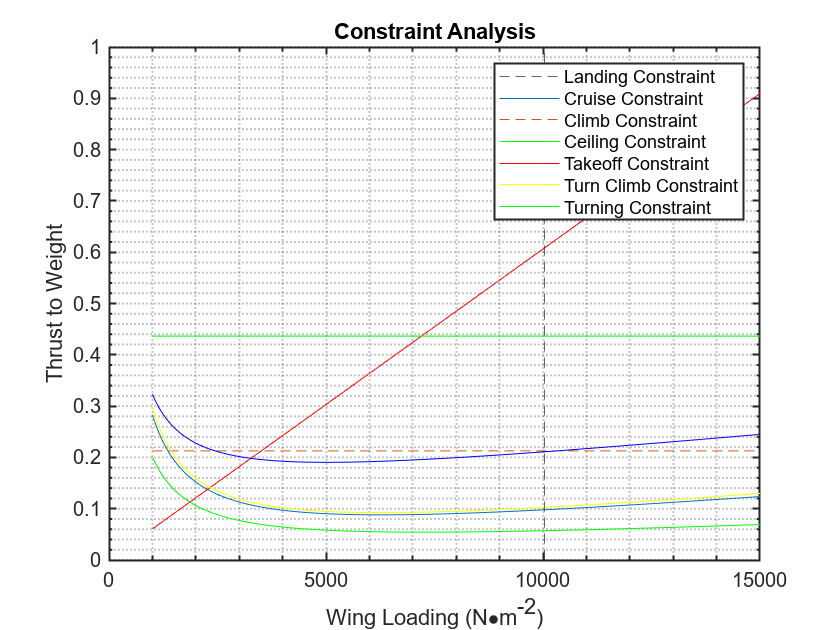

%Plotting Constrain analysis 
    %designPointX = 1200;
    %designPointY= 0.3;
    figure
    hold on 
    title("Constraint Analysis")
    legendData = ["Landing Constraint","Cruise Constraint","Climb Constraint","Ceiling Constraint",...
    "Takeoff Constraint"];
    xline(landingConstraint(1),"--")
    %area([landingConstraint,])
    plot(WingLoading,cruiseConstraint,"-")
    %area(WingLoading,cruiseConstraint,"FaceColor","r","FaceAlpha",0.3)
    plot(WingLoading,climbConstraint,"--")
    plot(WingLoading,ceilingConstraint, "g")
    plot(WingLoading,takeOffConstraint,"r") 
    plot(WingLoading, turningConstraint, "y")
    plot(WingLoading,   minimumTurningConstraint,"g")
   % plot(WingLoading,hightAltitudeTakeOff, "b")
   %area(WingLoading,takeOffConstraint,"FaceColor","r","FaceAlpha",0.3)
    if aircraftname == 'E'
    plot(WingLoading,turnClimbConstraint,"b")
    legendData = ["Landing Constraint","Cruise Constraint","Climb Constraint","Ceiling Constraint",...
    "Takeoff Constraint","Turn Climb Constraint","Turning Constraint"];
    end
    legend(legendData)
    xlabel("Wing Loading (N\bulletm^{-2})");
    ylabel("Thrust to Weight");
    

    %ax3 = gca;
    %chart4 = ax3.Children(1);
    %datatip(chart4,designPointX,designPointY);
    %chart4.DataTipTemplate.DataTipRows(1).Label="Wing Loading";
    %chart4.DataTipTemplate.Data  TipRows(2).Label="Thrust to Weight";

   set(gca,'XMinorTick','on')
    set(gca,'YMinorTick','on')
set(gca,'TickLength',[0.01 0.01])
set(gca,'LineWidth',1.0)
grid(gca,'minor') 
box(gca, 'on')
    hold off